**1. DCT and Walsh-Hadamard**

img = im2double(imread('mountain.tif'));  
if size(img, 3) == 3  
    img = rgb2gray(img);  
end

Compute the DCT of the image

dct_img = dct2(img); 

Compute log-scaled DCT coefficients

dct_scaled = log(1 + abs(dct_img));

Normalize to [0,1] for proper display

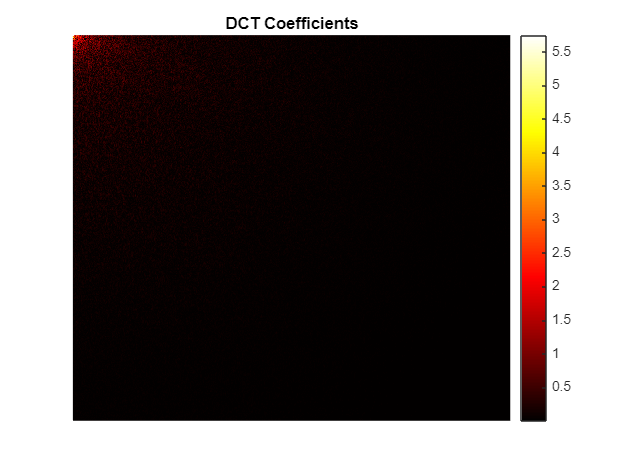

dct_scaled = (dct_scaled - min(dct_scaled(:))) / (max(dct_scaled(:)) - min(dct_scaled(:)));

figure;
imagesc(log(1 + abs(dct_img)));
colormap("hot");
colorbar;
axis off;
title('DCT Coefficients');

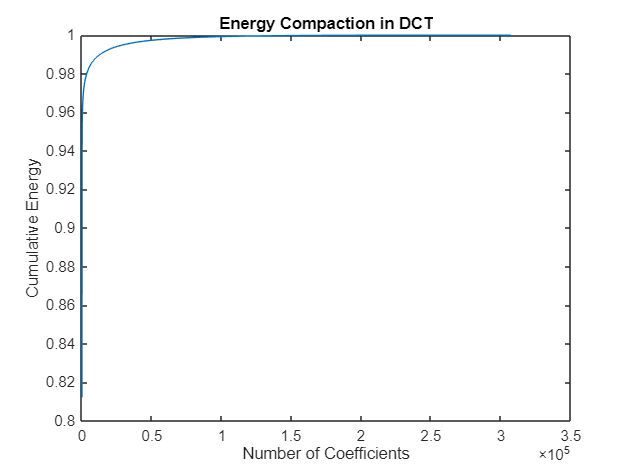

energy = sum(dct_img(:).^2);
sorted_coeffs = sort(abs(dct_img(:)), 'descend');
energy_cumsum = cumsum(sorted_coeffs.^2) / energy;

figure, plot(energy_cumsum), title('Energy Compaction in DCT');
xlabel('Number of Coefficients'); ylabel('Cumulative Energy');

**2. Calculate DCT matrix of order N = 8**

N = 8;
DCT_matrix = dctmtx(N);
disp('DCT Matrix of order 8:');

DCT Matrix of order 8:


disp(DCT_matrix);

    0.3536    0.3536    0.3536    0.3536    0.3536    0.3536    0.3536    0.3536
    0.4904    0.4157    0.2778    0.0975   -0.0975   -0.2778   -0.4157   -0.4904
    0.4619    0.1913   -0.1913   -0.4619   -0.4619   -0.1913    0.1913    0.4619
    0.4157   -0.0975   -0.4904   -0.2778    0.2778    0.4904    0.0975   -0.4157
    0.3536   -0.3536   -0.3536    0.3536    0.3536   -0.3536   -0.3536    0.3536
    0.2778   -0.4904    0.0975    0.4157   -0.4157   -0.0975    0.4904   -0.2778
    0.1913   -0.4619    0.4619   -0.1913   -0.1913    0.4619   -0.4619    0.1913
    0.0975   -0.2778    0.4157   -0.4904    0.4904   -0.4157    0.2778   -0.0975



**3. Plot the basis images of Walsh and Hadamard transformation of order N = 4**

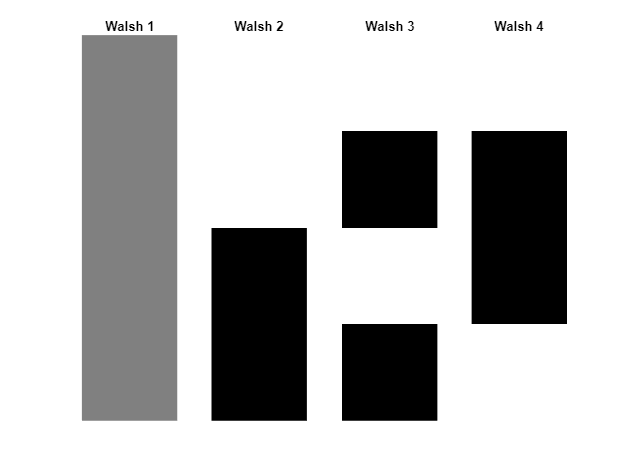

N = 4;
H = hadamard(N);
walsh_basis = H(bitrevorder(1:N), :);

figure;
for i = 1:N
    subplot(1, N, i);
    imagesc(walsh_basis(:, i)); colormap(gray);
    axis off; title(['Walsh ', num2str(i)]);
end

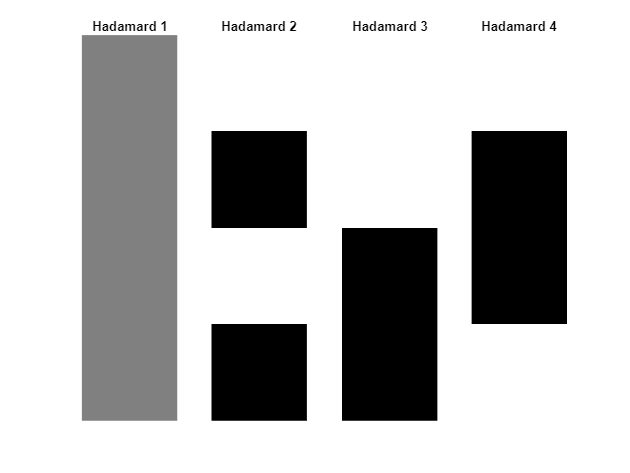

figure;
for i = 1:N
    subplot(1, N, i);
    imagesc(H(:, i)); colormap(gray);
    axis off; title(['Hadamard ', num2str(i)]);
end

**4. KL Transform & Reconstruction**

img = im2double(imread('image.png'));  
if size(img, 3) == 3  
    img = rgb2gray(img);  
end

block_size = 8;  
[m, n] = size(img);
X = im2col(img, [block_size block_size], 'distinct');  

X_mean = mean(X, 2);
X_centered = X - X_mean;
cov_matrix = (X_centered * X_centered') / size(X, 2);

[eig_vectors, eig_values] = eig(cov_matrix);
eig_values = diag(eig_values);
[~, idx] = sort(eig_values, 'descend');
eig_vectors = eig_vectors(:, idx);

K_values = [3, 10];
reconstructed_images = cell(1, length(K_values));

for i = 1:length(K_values)
    K = K_values(i);
    X_reduced = eig_vectors(:, 1:K)' * X_centered;  
    X_reconstructed = eig_vectors(:, 1:K) * X_reduced + X_mean;  
    reconstructed_images{i} = col2im(X_reconstructed, [block_size block_size], [m n], 'distinct');
end

Display Original, Reconstructed K=3, and K=10

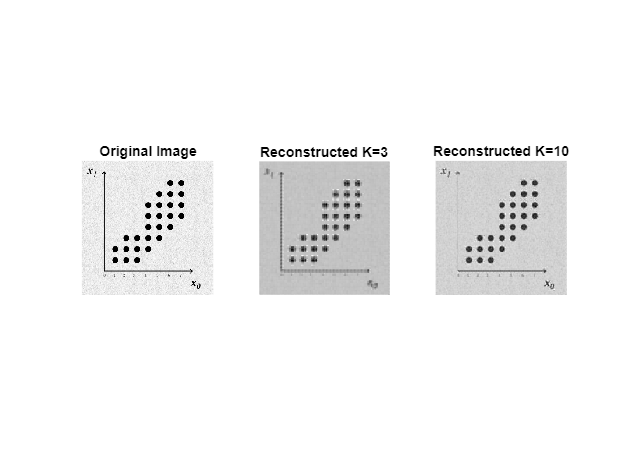

figure;
subplot(1,3,1), imshow(img, []), title('Original Image');
subplot(1,3,2), imshow(reconstructed_images{1}, []), title('Reconstructed K=3');
subplot(1,3,3), imshow(reconstructed_images{2}, []), title('Reconstructed K=10');

**5. KL Transform on 2D Vectors**

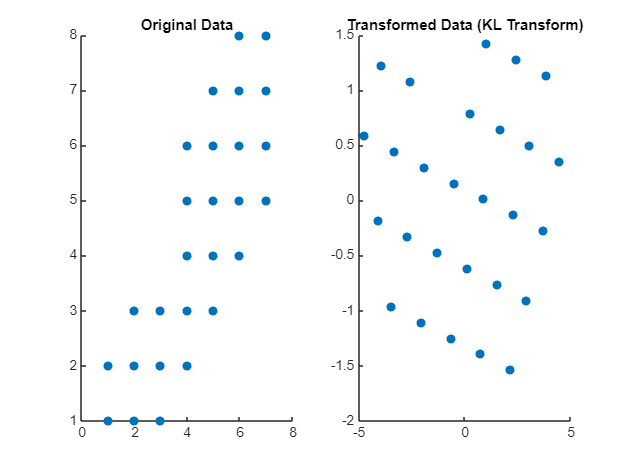

coordinates = [1,1; 1,2; 2,1; 2,2; 2,3; 3,1; 3,2; 3,3;
               4,2; 4,3; 4,4; 4,5; 4,6; 5,3; 5,4; 5,5;
               5,6; 5,7; 6,4; 6,5; 6,6; 6,7; 6,8; 7,5;
               7,6; 7,7; 7,8];

X = coordinates - mean(coordinates);

cov_matrix = cov(X);
[eig_vectors, eig_values] = eig(cov_matrix);
eig_values = diag(eig_values);
[~, idx] = sort(eig_values, 'descend');
eig_vectors = eig_vectors(:, idx);

X_transformed = X * eig_vectors;

figure;
subplot(1,2,1);
scatter(coordinates(:,1), coordinates(:,2), 'filled');
title('Original Data');

subplot(1,2,2);
scatter(X_transformed(:,1), X_transformed(:,2), 'filled');
title('Transformed Data (KL Transform)');